# Processing Hyperspectal Data from Coral Scans

Process raw hyperspectral data into labelled individual coral reflectance datasets for analysis. 

% Git Repository: https://github.com/AIMS/hyperspectral
% Only 1 HSI dataset in Reflectance folder
%
% Use tank name using HSI reflectance data as reference to extract
% corresponding labelsets
%
% Author: Jon Kok
% Last edited: 26/05/2022

## Define folders

Initialise script

% Clear workspace
clc
clear
close all

% Change directory to main script path
main_file_path = matlab.desktop.editor.getActiveFilename;
[main_file_path, ~, ~] = fileparts(main_file_path);
cd(main_file_path);

% Add function folders to path
addpath('MyFunctions')
% Addd data folders to path
addpath(genpath('Data'))

Define raw file source. Currently using local workspace. 

% Folder for reflectance data
folder_path_reflectance = 'Data/Reflectance';
% Folder for coral ground truthing labels
folder_path_ground_truth = 'Data/GroundTruth';
% Folder for extracted coral HSI
folder_path_extracted = 'Data/ExtractedCorals';

## Step 1: Coral segmentation from Grouth Truthing

Apply manually labelled ground truthing to reflectance HSI.

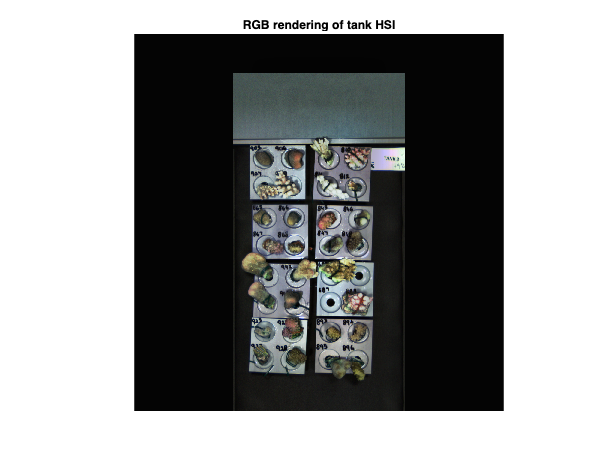

% Check HSI raw folder
content_rf_hdr = dir([folder_path_reflectance filesep '*.hdr']);
content_rf_bil = dir([folder_path_reflectance filesep '*.bil']);
content_rf_dat = dir([folder_path_reflectance filesep '*.dat']);
% Error check if more than 1 dataset in raw folder
if ~(length(content_rf_hdr) == 1 && (length(content_rf_bil) == 1 || length(content_rf_dat) == 1))
    error('Ensure that there is only one .hdr and one .bil file in Raw Folder.')
end
% Read HSI raw
rf_hsi_filename_full_path = [folder_path_reflectance filesep content_rf_hdr.name];
tank_rf_hsi = hypercubeMyFun(rf_hsi_filename_full_path);
tank_rf_rgb = colorize(tank_rf_hsi,'Method','rgb','contrastStretching',true);
% Save RGB rendering in reflectance folder, overwrite if already exist
tank_rf_tif_filename = [content_rf_hdr.name(1:end-7) 'tif'];
tank_rf_tif_filename_full_path = [folder_path_reflectance filesep tank_rf_tif_filename];
imwrite(tank_rf_rgb,tank_rf_tif_filename_full_path);
imshow(tank_rf_rgb)
title('RGB rendering of tank HSI')

% Read data ground truth
content_gtruth = dir([folder_path_ground_truth filesep '*.mat']);
if ~(length(content_gtruth) == 1)
    error('Ensure that there is only one grouth truth .mat GroundTruth Folder.')
end
gtruth_filename_full_path = [folder_path_ground_truth filesep content_gtruth.name];
load(gtruth_filename_full_path)
% Ignore warning regarding datasource filenames cannot be found
% Find datasource that matches reflectance filename
filename_ffc_index = strfind(tank_rf_tif_filename,'_ffc');
filename_rf_index = strfind(tank_rf_tif_filename,'_rf');
filename_end_index = min([filename_rf_index filename_ffc_index]);
tank_name = tank_rf_tif_filename(1:filename_end_index-1);
% Read source file names
source_filename_array = gTruth.DataSource.Source;
% Convert source file names to tank names
% Catch for linux vs windows file separator
filename_forward_slash_index = strfind(source_filename_array,'/');
filename_backward_slash_index = strfind(source_filename_array,'\');
if isempty(filename_backward_slash_index{1})
    filename_slash_index = filename_forward_slash_index;
else
    filename_slash_index = filename_backward_slash_index;
end
source_index = 0;
for n = 1:length(source_filename_array)
    filename_index = filename_slash_index{n}(end);
    source_filename = source_filename_array{n}(filename_index+1:end);
    if strfind(source_filename,tank_name) == 1 
        source_index = n;
    end
end
if source_index == 0
    error('DataSource tank file names in Reflectance and GrouthTruth folders does not match.')
end
% Find all labelled corals
label_name_array = gTruth.LabelData.Properties.VariableNames;
label_cell_array = table2array(gTruth.LabelData);
for m = 1:length(label_name_array)
    if ~isempty(label_cell_array{source_index,m})
        % Label polygon
        label_array = cell2mat(label_cell_array{source_index,m});
        coral_bw_mask = roipoly(tank_rf_rgb,label_array(:,1),label_array(:,2));
        % Label name
        label_name = cell2mat(label_name_array(m));
        % Crop HSI
        coral_hsi_mask_applied = maskCropHsi(tank_rf_hsi,coral_bw_mask);
        coral_rgb = colorize(coral_hsi_mask_applied,'Method','rgb','ContrastStretching',true);
        % Save HSI and RGB in same local folder
        coral_hsi_filename = [tank_name '_' label_name '.bil.hdr'];
        coral_hsi_filename_full_path = [folder_path_extracted filesep coral_hsi_filename];
        coral_rgb_filename = [tank_name '_' label_name '.tif'];
        coral_rgb_filename_full_path = [folder_path_extracted filesep coral_rgb_filename]
        enviwriteMyFun(coral_hsi_mask_applied,coral_hsi_filename_full_path);
        imwrite(coral_rgb,coral_rgb_filename_full_path);
    end
end

coral_rgb_filename_full_path = 'Data/Extracted/Tank 3_coral_1.tif'

coral_rgb_filename_full_path = 'Data/Extracted/Tank 3_coraL2.tif'

coral_rgb_filename_full_path = 'Data/Extracted/Tank 3_coral_3.tif'



% Rea
%% Extract polygon from reference HSI
% Read coral images
coral_image_filename_full_path_array = gTruth.DataSource.Source;

scene_index = 1;
coral_tif_filename_full_path = coral_image_filename_full_path_array{scene_index};
path_start_index = find(coral_tif_filename_full_path == '/',4,'last');
coral_tif_ref_path = coral_tif_filename_full_path(path_start_index(1):end);
coral_tif_filename = coral_tif_filename_full_path(path_start_index(end)+1:end);

% Find corresponding coral image
coral_rgb_ref_contents = dir([coral_folder_local_full_path '/**/*.tif']);

Unrecognized function or variable 'coral_folder_local_full_path'.

coral_rgb_ref_array = strcat({coral_rgb_ref_contents.folder},filesep,{coral_rgb_ref_contents.name});
coral_rgb_ref_found = contains(coral_rgb_ref_array,coral_tif_filename);
coral_rgb_ref_index = find(coral_rgb_ref_found == 1); 

if length(coral_rgb_ref_index) ~= 1
    error('None or more than 1 index found.')
end

coral_image_ref_full_path = cell2mat(coral_rgb_ref_array(coral_rgb_ref_index));
coral_image = imread(coral_image_ref_full_path);

figure
imshow(coral_image)
scene_index = 1
% Find all labelled corals
label_name_array = gTruth.LabelData.Properties.VariableNames;
label_cell_array = table2array(gTruth.LabelData);
for m = 1:length(label_name_array)
    if ~isempty(label_cell_array{scene_index,m})
        % label polygon
        label_array = cell2mat(label_cell_array{scene_index,m});
        coral_bw_mask = roipoly(coral_image,label_array(:,1),label_array(:,2));
        % label name
        label_name = cell2mat(label_name_array(m));
        % Crop HSI
        coral_hsi_full_path = [coral_folder_local_full_path filesep coral_tif_filename(1:end-8) '.bil.hdr'];
        coral_hsi_scene = hypercubeMyFun(coral_hsi_full_path);
        coral_hsi_mask_applied = maskCropHsi(coral_hsi_scene,coral_bw_mask);
        coral_rgb = colorize(coral_hsi_mask_applied,"Method","rgb","ContrastStretching",true);
        % Save HSI and RGB in same local folder
        coral_hsi_filename = [coral_hsi_full_path(1:end-8) '_' label_name '.bil.hdr'];
        coral_rgb_filename = [coral_hsi_full_path(1:end-8) '_' label_name '.tif'];
        enviwriteMyFun(coral_hsi_mask_applied,coral_hsi_filename);
        imwrite(coral_rgb,coral_rgb_filename);
    end
end



## Step 4: Coral extraction

Apply manually labelled ground truthing to reflectance

## Step 5: Feature extraction

Extract features for analysis. E.g., median of 650nm, number of pixels

## Step 6: Feature analysis

Classification, correlation or other analysis on features.